# C/GMREによる4輪の衝突回避問題

## 初期化

clc,clear

## プラントモデルを定式化

4輪の前輪操舵車両を考える。等価二輪モデルで近似する（図1）。

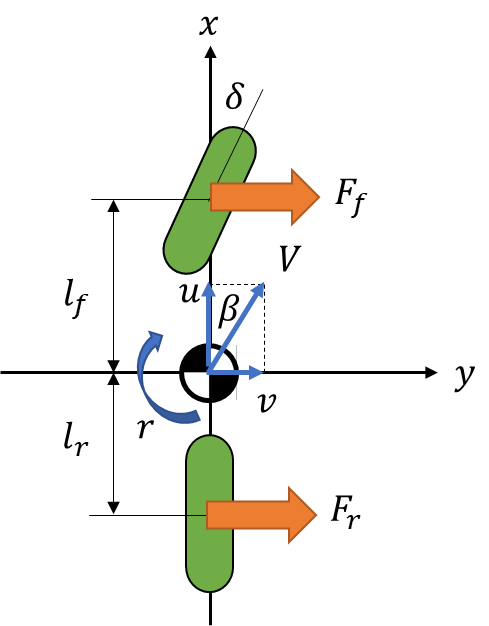

図1. 等価二輪モデル

ここで、等価二輪モデルの数式を元にプラントモデリングとMPCの定式化を行っていく。このモデルにおいては、以下の式eq_1, eq_2が成り立つ。

% 変数定義
m = sym('m','real');        %車体質量
u = sym('u','real');        %縦方向速度
v = sym('v','real');        %横方向速度
r = sym('r','real');        %ヨーレート
F_f = sym('F_f','real');    %前輪の横力
F_r = sym('F_r','real');    %後輪の横力
I = sym('I','real');        %Z軸回りの慣性モーメント
l_f = sym('l_f','real');    %車両中心から前輪回転中心までの距離
l_r = sym('l_r','real');    %車両中心から後輪回転中心までの距離
v_dot = sym('v_dot','real');    %縦方向加速度
r_dot = sym('r_dot','real');    %ヨー角加速度
V = sym('V','real');            %車両進行方向の速度
beta = sym('beta','real');      %横滑り角
beta_dot = sym('beta_dot','real');  %横滑り角速度

% 方程式
eq_1 = m * (v_dot + u * r) == F_f + F_r

$$eq\_1 = m\,\left(\dot{v}+r\,u\right)=F_{f}+F_{r}$$

eq_2 = I * r_dot == l_f * F_f - l_r * F_r

$$eq\_2 = \text{I}\,\dot{r}=F_{f}\,l_{f}-F_{r}\,l_{r}$$

ここで、$v$は横速度、$r$は車のヨーレート（z軸方向の回転角速度）である。$\dot{v}$と$\dot{r}$はそれぞれ$v$と$r$の時間微分を表す。$F_f$と$F_r$は前後のタイヤから発生する横向きの力を表す。

車体の横滑り角$\beta \;$が小さい範囲の運動を考えることにすると、次のような関係が成り立つ。

$u\cong V$, $v=\textrm{Vsin}\beta \cong V\beta \;$

速度を一定と仮定すると、$\dot{v}$は以下のようになる。


$$\dot{v} =V\beta^˙ \;$$


これらの関係を用いると、eq_1は、以下のように書き直すことができる。

% 代入
eq_1 = subs(eq_1, [u, v_dot], [V, V * beta_dot])

$$eq\_1 = m\,\left(V\,\dot{\beta }+V\,r\right)=F_{f}+F_{r}$$

前後のタイヤの横滑り角を$\beta_f$、$\beta_r$とすると、横力は

$F_f =-2K_f \beta_f$,  $F_r =-2K_r \beta {\;}_r$

となる。

また、$\beta_f$と$\beta_r$は近似的に次のように表すことができる。

$\beta_f =\beta +\frac{l_f }{V}r-\delta$,  $\beta_r =\beta -\frac{l_r }{V}r$

$\delta$は操舵角である。

eq_1、eq_2に上記の式を代入すると、以下のようになる。

% 変数定義
K_f = sym('K_f','real'); K_r = sym('K_r','real'); delta = sym('delta','real');
beta_f = sym('beta_f','real'); beta_r = sym('beta_r','real');
% 代入
eq_vec = subs([eq_1, eq_2], [F_f, F_r], [-2*K_f*beta_f, -2*K_r*beta_r]);
eq_vec = subs(eq_vec, [beta_f, beta_r], ...
    [beta+(l_f/V)*r-delta, beta-(l_r/V)*r]);
eq_1 = eq_vec(1)

$$eq\_1 = m\,\left(V\,\dot{\beta }+V\,r\right)=-2\,K_{f}\,\left(\beta -\delta +\frac{l_{f}\,r}{V}\right)-2\,K_{r}\,\left(\beta -\frac{l_{r}\,r}{V}\right)$$

eq_2 = eq_vec(2)

$$eq\_2 = \text{I}\,\dot{r}=2\,K_{r}\,l_{r}\,\left(\beta -\frac{l_{r}\,r}{V}\right)-2\,K_{f}\,l_{f}\,\left(\beta -\delta +\frac{l_{f}\,r}{V}\right)$$

$\beta^˙$と$\dot{r}$を求める計算式を導出する。

sol_vec = solve([eq_1, eq_2], [beta_dot, r_dot]);
beta_dot = sol_vec.beta_dot

$$beta\_dot = -\frac{2\,K_{f}\,V\,\beta +2\,K_{r}\,V\,\beta -2\,K_{f}\,V\,\delta +2\,K_{f}\,l_{f}\,r-2\,K_{r}\,l_{r}\,r+V^{2}\,m\,r}{V^{2}\,m}$$

r_dot = sol_vec.r_dot

$$r\_dot = -\frac{2\,\left(K_{f}\,{l_{f}}^{2}\,r+K_{r}\,{l_{r}}^{2}\,r+K_{f}\,V\,\beta \,l_{f}-K_{r}\,V\,\beta \,l_{r}-K_{f}\,V\,\delta \,l_{f}\right)}{\text{I}\,V}$$

$\beta$と$r$は、$\beta^˙$と$\dot{r}$を時間積分することで得られる。

## 状態空間表現

車両の運動を状態空間表現に置き換える。

[入力U]

操舵角$\delta$、車両加速度$a$

% 変数定義
a = sym('a','real');
U = delta;  % アクセル一定
% normal_input_names = {'delta', 'a'};

[状態x]

横滑り角$\beta$、ヨーレート$r$、ヨー角$\theta$、X方向位置$p_x$、Y方向位置$p_y$

% 変数定義
theta = sym('theta','real'); px = sym('px','real'); py = sym('py','real');
X = [px; py; theta; r; beta];
% state_names = {'px', 'py', 'theta', 'r', 'beta'};

連続非線形の状態方程式$\dot{X} =f\left(X,U\right)$の$f$を作る。


$$\dot{x} =\textrm{Vsin}\left(\beta +\theta \right)$$



$$\dot{y} =\textrm{Vcos}\left(\beta +\theta \right)\;$$



$$\theta^˙ =r$$


$\dot{r} =$sol_vec.r_dot

$\beta^˙ =$sol_vec.beta_dot

よって、

f = [ ...
    V * cos(theta+beta);
    V * sin(theta+beta);
    r;
    sol_vec.r_dot;
    sol_vec.beta_dot;
    ]

$$f = \left(\begin{array}{c} V\,\cos\left(\beta +\theta \right)\\ V\,\sin\left(\beta +\theta \right)\\ r\\ -\frac{2\,\left(K_{f}\,{l_{f}}^{2}\,r+K_{r}\,{l_{r}}^{2}\,r+K_{f}\,V\,\beta \,l_{f}-K_{r}\,V\,\beta \,l_{r}-K_{f}\,V\,\delta \,l_{f}\right)}{\text{I}\,V}\\ -\frac{2\,K_{f}\,V\,\beta +2\,K_{r}\,V\,\beta -2\,K_{f}\,V\,\delta +2\,K_{f}\,l_{f}\,r-2\,K_{r}\,l_{r}\,r+V^{2}\,m\,r}{V^{2}\,m} \end{array}\right)$$

## CGMRESのための定式化

CGMRESでは以下の評価関数を元に算出を行う。


$$J=\varphi \left(x\left(\textrm{tf}\right),\textrm{tf}\right)+\int_{\textrm{t0}}^{\textrm{tf}} L\left(x\left(\tau \right),u\left(\tau \right),\tau \right)d\tau$$


上式において$\varphi$は終端コスト、$L$はステージコストを意味する。

今回、衝突回避のために各コスト項は次式を用いる。


$$\varphi \left(x\left(\textrm{tf}\right),\textrm{tf}\right)={\frac{1}{2}x\left(\textrm{tf}\right)}^T Q_f x\left(\textrm{tf}\right)$$



$$L\left(x\left(\tau \right),u\left(\tau \right),\tau \right)=\frac{1}{2}\left\lbrace {x\left(\tau \right)}^T Q\;x\left(\tau \right)+{u\left(\tau \right)}^T R\;u\left(\tau \right)-p\left(\mathrm{log}\left(-\mathrm{py}+W\right)\left(\mathrm{py}+W\right)+\mathrm{log}\left({-\mathrm{radius}}^2 +{\mathrm{px}}^2 +{\mathrm{py}}^2 \right)\right)\right\rbrace$$


衝突回避問題では、障害物が道路に固定した慣性座標系の原点に位置すると仮定し、かつ円柱状の物体であるとする。

そうすると、衝突回避のためには、障害物の半径以内に入らないようにすることが制約となる。

また道路には境界があるとして定められた道幅の中で障害物を回避することを制御目的とする。

% 定式化のためのパラメーター定義
q_f1 = sym('q_f1','real');q_f2 = sym('q_f2','real');q_f3 = sym('q_f3','real');
q_f4 = sym('q_f4','real');q_f5 = sym('q_f5','real');
Q_f = diag([q_f1,q_f2,q_f3,q_f4,q_f5]);  % 終端重み

q_1 = sym('q_1','real');q_2 = sym('q_2','real');q_3 = sym('q_3','real');
q_4 = sym('q_4','real');q_5 = sym('q_5','real');
Q = diag([q_1,q_2,q_3,q_4,q_5]);          % 状態量重み

R = sym('R',[1,1],'real');      % 入力重み
W = sym('W','real');            % 道路幅の制約値
radius = sym('radius','real');  % 障害物の半径
p = sym('p','real');            % バリア関数のペナルティ重み
ref = sym('ref',[5,1],'real');  % 基準状態量
s = sym('s','real');            % スラック変数
w_s = sym('w_s','real');        % スラック変数の重み
rho = sym('rho','real');        % 等式制約のラグランジュ乗数
U = [U;s;rho];                  % スラック、ラグランジュ乗数を含めた入力ベクトル

% 操作量の上下限制約
delta_max = sym('delta_max','real');  % ステアリング舵角の上下限
C = delta^2+s(1)^2-delta_max^2;

% 終端コスト
PHI = 0.5*(X-ref)'*Q_f*(X-ref);

% ステージコスト
L = 0.5*((X-ref)'*Q*(X-ref)+U(1)'*R*U(1))-p*(log((-py+W)*(py+W))+log(-radius^2+(px^2+py^2)))-w_s'*s;

% ハミルトニアンの算出
% ラグランジュ乗数（共状態）
lamda = sym('lamda',[5,1],'real');
H = simplify(L + lamda'*f + rho'*C)

$$H = {\mathrm{lamda}}_{3}\,r-p\,\left(\log\left(\left(W+\mathrm{py}\right)\,\left(W-\mathrm{py}\right)\right)+\log\left({\mathrm{px}}^{2}+{\mathrm{py}}^{2}-{\mathrm{radius}}^{2}\right)\right)-s\,w_{s}+\frac{R_{1}\,\delta^{2}}{2}+\frac{q_{5}\,{\left(\beta -{\mathrm{ref}}_{5}\right)}^{2}}{2}+\frac{q_{1}\,{\left(\mathrm{px}-{\mathrm{ref}}_{1}\right)}^{2}}{2}+\frac{q_{2}\,{\left(\mathrm{py}-{\mathrm{ref}}_{2}\right)}^{2}}{2}+\frac{q_{4}\,{\left(r-{\mathrm{ref}}_{4}\right)}^{2}}{2}+\frac{q_{3}\,{\left({\mathrm{ref}}_{3}-\theta \right)}^{2}}{2}+\rho \,\left(\delta^{2}-{\delta_{\max}}^{2}+s^{2}\right)+V\,{\mathrm{lamda}}_{1}\,\cos\left(\beta +\theta \right)+V\,{\mathrm{lamda}}_{2}\,\sin\left(\beta +\theta \right)-\frac{2\,{\mathrm{lamda}}_{4}\,\left(K_{f}\,{l_{f}}^{2}\,r+K_{r}\,{l_{r}}^{2}\,r+K_{f}\,V\,\beta \,l_{f}-K_{r}\,V\,\beta \,l_{r}-K_{f}\,V\,\delta \,l_{f}\right)}{\text{I}\,V}-\frac{{\mathrm{lamda}}_{5}\,\left(2\,K_{f}\,V\,\beta +2\,K_{r}\,V\,\beta -2\,K_{f}\,V\,\delta +2\,K_{f}\,l_{f}\,r-2\,K_{r}\,l_{r}\,r+V^{2}\,m\,r\right)}{V^{2}\,m}$$

dHdx = simplify(gradient(H,X))

$$dHdx = \begin{array}{l} \left(\begin{array}{c} \frac{q_{1}\,\left(2\,\mathrm{px}-2\,{\mathrm{ref}}_{1}\right)}{2}-\frac{2\,p\,\mathrm{px}}{\sigma_{1}}\\ \frac{q_{2}\,\left(2\,\mathrm{py}-2\,{\mathrm{ref}}_{2}\right)}{2}-p\,\left(\frac{2\,\mathrm{py}}{\sigma_{1}}-\frac{2\,\mathrm{py}}{\left(W+\mathrm{py}\right)\,\left(W-\mathrm{py}\right)}\right)\\ \sigma_{3}-\frac{q_{3}\,\left(2\,{\mathrm{ref}}_{3}-2\,\theta \right)}{2}-\sigma_{2}\\ {\mathrm{lamda}}_{3}+q_{4}\,\left(r-{\mathrm{ref}}_{4}\right)-\frac{{\mathrm{lamda}}_{5}\,\left(m\,V^{2}+2\,K_{f}\,l_{f}-2\,K_{r}\,l_{r}\right)}{V^{2}\,m}-\frac{2\,{\mathrm{lamda}}_{4}\,\left(K_{f}\,{l_{f}}^{2}+K_{r}\,{l_{r}}^{2}\right)}{\text{I}\,V}\\ \frac{q_{5}\,\left(2\,\beta -2\,{\mathrm{ref}}_{5}\right)}{2}+\sigma_{3}-\sigma_{2}-\frac{2\,{\mathrm{lamda}}_{4}\,\left(K_{f}\,V\,l_{f}-K_{r}\,V\,l_{r}\right)}{\text{I}\,V}-\frac{{\mathrm{lamda}}_{5}\,\left(2\,K_{f}\,V+2\,K_{r}\,V\right)}{V^{2}\,m} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{px}}^{2}+{\mathrm{py}}^{2}-{\mathrm{radius}}^{2}\\ \sigma_{2}=V\,{\mathrm{lamda}}_{1}\,\sin\left(\beta +\theta \right)\\ \sigma_{3}=V\,{\mathrm{lamda}}_{2}\,\cos\left(\beta +\theta \right) \end{array}$$

dHdu = simplify(gradient(H,U))

$$dHdu = \left(\begin{array}{c} R_{1}\,\delta +2\,\delta \,\rho +\frac{2\,K_{f}\,l_{f}\,{\mathrm{lamda}}_{4}}{\text{I}}+\frac{2\,K_{f}\,{\mathrm{lamda}}_{5}}{V\,m}\\ 2\,\rho \,s-w_{s}\\ \delta^{2}-{\delta_{\max}}^{2}+s^{2} \end{array}\right)$$

ddHddu = simplify(jacobian(dHdu,U))

$$ddHddu = \left(\begin{array}{ccc} R_{1}+2\,\rho & 0 & 2\,\delta \\ 0 & 2\,\rho & 2\,s\\ 2\,\delta & 2\,s & 0 \end{array}\right)$$

dPHIdx = simplify(gradient(PHI,X))

$$dPHIdx = \left(\begin{array}{c} q_{\mathrm{f1}}\,\left(\mathrm{px}-{\mathrm{ref}}_{1}\right)\\ q_{\mathrm{f2}}\,\left(\mathrm{py}-{\mathrm{ref}}_{2}\right)\\ -q_{\mathrm{f3}}\,\left({\mathrm{ref}}_{3}-\theta \right)\\ q_{\mathrm{f4}}\,\left(r-{\mathrm{ref}}_{4}\right)\\ q_{\mathrm{f5}}\,\left(\beta -{\mathrm{ref}}_{5}\right) \end{array}\right)$$

matlabFunction(dHdx,'File','dHdx');
matlabFunction(dHdu,'File','dHdu');
matlabFunction(ddHddu,'File','ddHddu');
matlabFunction(dPHIdx,'File','dPHIdx');

## シミュレーション

% state_names = {'px', 'py', 'theta', 'r', 'beta', 'V'};
% normal_input_names = {'delta'};
% パラメータ
m_val = 2000;
l_f_val = 1.4;
l_r_val = 1.6;
I_val = 4000;
K_f_val = 12e3;
K_r_val = 11e3;

% 初期状態量
x0 = [-50;0;0;0;0];
% サンプリング時間 
Ts = 1e-4;

params.Qf = [0;0;100;0;0];
params.Q = [-100;-100;100;0;0];
params.R = 10;
params.PredictiveTime = 1;
params.divideNumber = 100;
params.MV_max = 50*pi/180;                   % Inputs Constraints
params.zeta = 1/Ts;                            % Decay coefficient
params.stateFunction = 'stateFcn';
params.jacobianTerminalFunction = 'wrap_dPhidx';
params.jacobianHamiltonianState = 'wrap_dHdx';
params.jacobianHamiltonianInput = 'wrap_dHdu';
params.IterationMax = 1000;

% Reference value
ref = zeros(5,1);

%Calculation for initial inputs which is satisfied "dh/du = 0" by Newton method
u0 = rand(3,1);
lamda0 = wrap_dPhidx(x0,ref,params);
while(true)
    u0 = u0 - wrap_ddHddu(x0,lamda0,u0,0,ref,params) \ wrap_dHdu(x0,lamda0,u0,0,ref,params);
    if norm(wrap_dHdu(x0,lamda0,u0,0,ref,params)) < 1e-6
        disp('Newton mathod was converged!')
        params.initialConditionInputs = u0;
        break;
    end
end

Newton mathod was converged!


Tsim = 10;
mdl = 'laneChangeNonLinCar';
open_system(mdl)
sim(mdl,Tsim)

プログラムの割り込み (Ctrl-C) が検出されました。